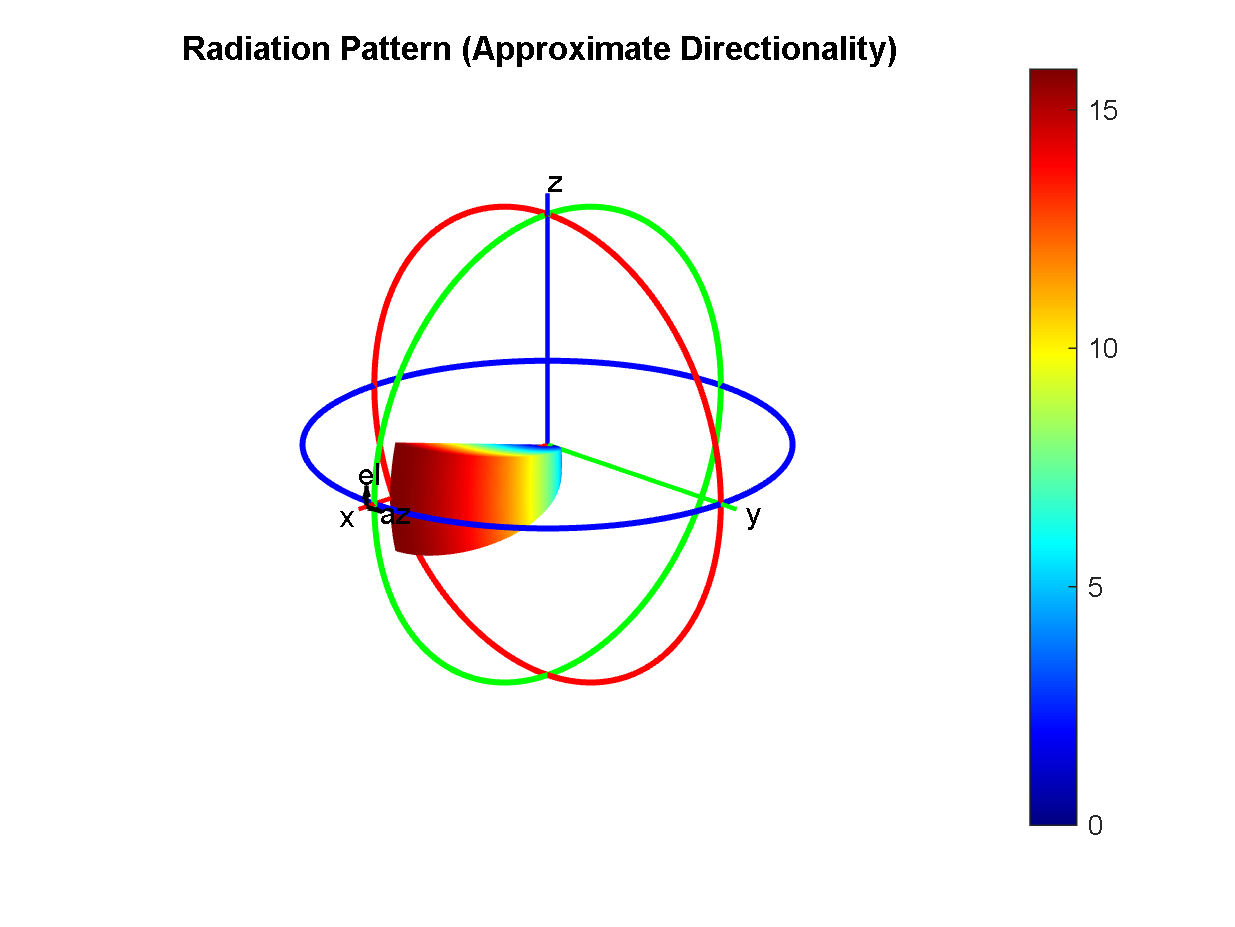

Unrecognized function or variable 'object'.

% Define parameters
freq = 915e6; % Frequency in Hz

% Define elevation and azimuth angles
elevation = -90:1:90; % Elevation angle range (degrees)
azimuth = 0:1:360; % Azimuth angle range (degrees)

% Calculate radiation pattern
pattern_data = zeros(length(elevation), length(azimuth));

% Calculate main lobe pattern (cosine-squared pattern)
main_lobe_azimuth = 90; % Azimuth angle of the main lobe peak (degrees)
main_lobe_width = 30; % Width of the main lobe (degrees)
main_lobe_gain = 12; % Maximum gain of the main lobe (dBd)

% Calculate gain for main lobe
main_lobe_gain_lin = 10^(main_lobe_gain/10);
for i = 1:length(elevation)
    for j = 1:length(azimuth)
        if abs(azimuth(j) - main_lobe_azimuth) <= main_lobe_width/2 && elevation(i) >= 0
            pattern_data(i, j) = main_lobe_gain_lin * cosd(elevation(i))^2;
        end
    end
end

% Plot the radiation pattern
figure;
patternCustom(pattern_data, azimuth, elevation);

% Set title and labels
title('Radiation Pattern (Approximate Directionality)');
xlabel('Azimuth (degrees)');
ylabel('Elevation (degrees)');